# **System 5 : Gekoppelte Pendel**

Das System von zwei gekoppelten Differentialgleichungen lautet:


$$\ddot x_1 + \frac{g}{l}\ * x_1 +\frac{m}{k}\ * (x_1 - x_2) = 0
$$



$$\ddot x_2 + \frac{g}{l}\ * x_2 +\frac{m}{k}\ * (x_2 - x_1) = 0$$


Parameterset : mit $x_1 = 0.05m \  \  x_2 = 0m  \\ m = 0.10kg \ \  l = 0.50m \  \ k = 5.00Nm^{-1}  \  \ g = 9.81$

Wie beeinflussen die einzelnen Parameterden Attraktor?

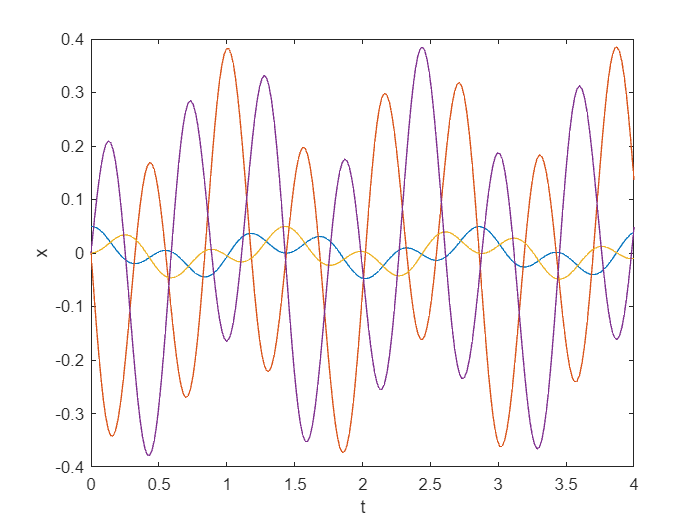

clc
close
clear

%Parameterset 
m = 0.1;
l = 0.5;
k = 5;
g = 10;
x0 = [0.05 0 0 0];
tSpan = [0 4];
% D2x1 = (-g/l)*x1 + (k/m)*(x2-x1);
% D2x2 = (-g/l)*x2 + (k/m)*(x1-x2);
% ode1 = diff(x1,2) == (-g/l)*x1 + (k/m)*(x2-x1);
% ode2 = diff(x2,2) == (-g/l)*x2 + (k/m)*(x1-x2);
% odes = [ode1; ode2]
% 
% cond1 = x1(0) == 0.05;
% cond2 = x2(0) == 0;
% conds = [cond1; cond2];
% [x1Sol(t),x2Sol(t)] = dsolve(odes,conds)
% 
% s = dsolve(odes);

%Define x(1)=x1, x(2)=x(1)', x(3)=x2, x(4)=x(3)';
dx = @(t,x)[x(2); ((-g/l)*x(1)+(k/m)*(x(3)-x(1))); x(4); ((-g/l)*x(3)+(k/m)*(x(1)-x(3)))];
[t,x] = ode45(dx,tSpan,x0);

plot(t,x);
xlabel("t")
ylabel("x")

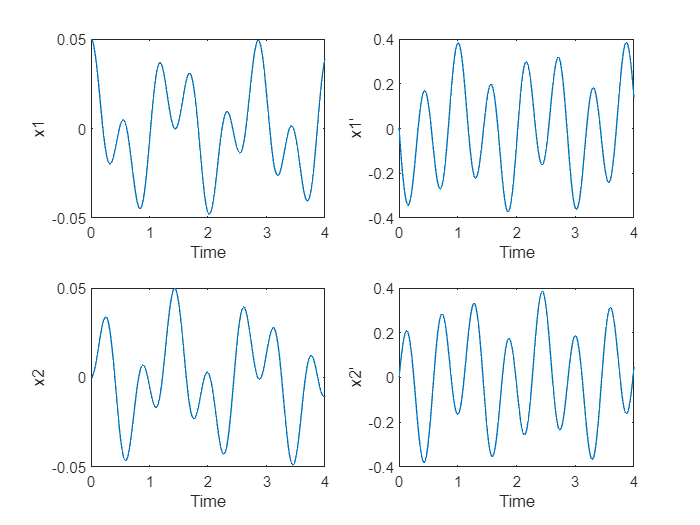


lstr = { 'x1', 'x1''', 'x2', 'x2''' };
for i=1:length(lstr)
    subplot(2,2,i)
    plot(t, x(:,i));
    xlabel('Time')
    ylabel( lstr{i} )
end